clear;clc;

img = imread('lena.bmp')

img = 256×256 uint8 矩阵
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   137   136   133   136   138   134   134   132   132   138   129   131   132   127   129   129   130   131   138   138   142   146   151   151   149   148   143   134   119   118    90    80    64    62    61    69    71    73    73    74    78    74    76    79    76    75    78    76    78    78
   138   133   134   134   136   132   130   130   131   134   128   127   131   128   128   130   130   128   136   138   142   146   150   150   149   148   143   132   119   111    88    78    65    61    60    66    70    69    73    74    75    74    73    76    73    73    76    73    76    76
   133   133   133   130   134   133   128   125   129   128   128   125  

[height, width] = size(img)

height = 256

width = 256


s = 2  % sample rate

s = 2

supersampledx = zeros(height * s, width * s)

supersampledx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

supersampled = zeros(height * s, width * s)

supersampled =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    


for a = 1:s
    for i = 1+a-1:s:width*s
        supersampledx(1:height,i) = img(:,(i+(s-a))/s)
    end
end

supersampledx =    137     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0     0     0     0     0     0     0     0     0     0     0     0   

supersampledx =    137     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0     0     0     0     0     0     0     0     0     0   

supersampledx =    137     0   136     0   133     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0     0     0     0     0     0     0     0   

supersampledx =    137     0   136     0   133     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0     0     0     0     0     0   

supersampledx =    137     0   136     0   133     0   136     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0     0     0     0   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0     0   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0     0     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0     0     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0     0     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0     0     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0     0     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0     0     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0     0     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0     0     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0     0     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0     0     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0     0     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0     0     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0     0     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0     0     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0     0     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0     0     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0     0     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx =    137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0   129     0   130     0   131     0   138     0   138     0   142     0   146     0   151     0   151     0   149     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0   130     0   130     0   128     0   136     0   138     0   142     0   146     0   150     0   150     0   149     0
   133     0   133     0   133     0   130     0   134     0   133     0   128   

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137     0   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138     0   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133     0   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129     0   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131     0   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137   137   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136     0   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133     0   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133     0   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133     0   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133     0   130     0   122     0   132     0   131     

supersampledx = 512×512
   137   137   136   136   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133     0   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134     0   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133     0   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130     0   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130     0   122     0   132     0   131     

supersampledx = 512×512
   137   137   136   136   133   133   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136     0   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134     0   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130     0   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130     0   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122     0   132     0   131     

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138     0   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136     0   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134     0   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133     0   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132     0   131     

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134     0   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132     0   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133     0   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131     0   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131     

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134     0   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130     0   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128     0   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132     0   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132     0   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130     0   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125     0   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128     0   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132     0   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131     0   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129     0   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128     0   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138     0   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138     0   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134     0   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128     0   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131     0   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129     0   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129     0   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128     0   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128     0   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130     0   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131     0   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131     0   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127     0   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125     0   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126     0   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132     0   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132     0   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131     0   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129     0   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129     0   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127     0   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127     0   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128     0   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127     0   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126     0   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128     0
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123     0
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126     0
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13

supersampledx = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   133   133   133   133   133   133   130   130   134   134   133   133   128   128   125   125   129   129   128   128   128   128   125   125   129   129   127   127   123   123
   129   129   133   133   130   130   130   130   133   133   131   131   132   132   128   128   128   128   131   131   130   130   126   126   129   129   126   126   126   126
   131   131   133   133   130   130   122   122   132   132   131   13


for a = 1:s
    for j = 1+a-1:s:width*s
        supersampled(j,:) = supersampledx((j+(s-a))/s,:)
    end
end

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
     0     0     0     0     0     0     0     0     0     0     0     0

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

supersampled = 512×512
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   137   137   136   136   133   133   136   136   138   138   134   134   134   134   132   132   132   132   138   138   129   129   131   131   132   132   127   127   129   129
   138   138   133   133   134   134   134   134   136   136   132   132   130   130   130   130   131   131   134   134   128   128   127   127   131   131   128   128   128   128
   138   138   133   133   134   134   134   134   136   136   132   132

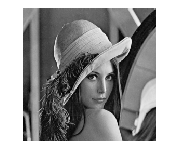


% for i = 1:2:width*2
%     supersampledx(1:height,i) = img(:,(i+1)/2)
% end
% for i = 2:2:width*2
%     supersampledx(1:height,i) = img(:,i/2)
% end

% for j = 1:2:height*2
%     supersampled(j,:) = supersampledx((j+1)/2,:)
% end
% for j = 2:2:height*2
%     supersampled(j,:) = supersampledx(j/2,:)
% end

imshow(supersampled, [])